# **Welcome to Deci**

**A fluid pipeline to analyze EEG Data with ease**

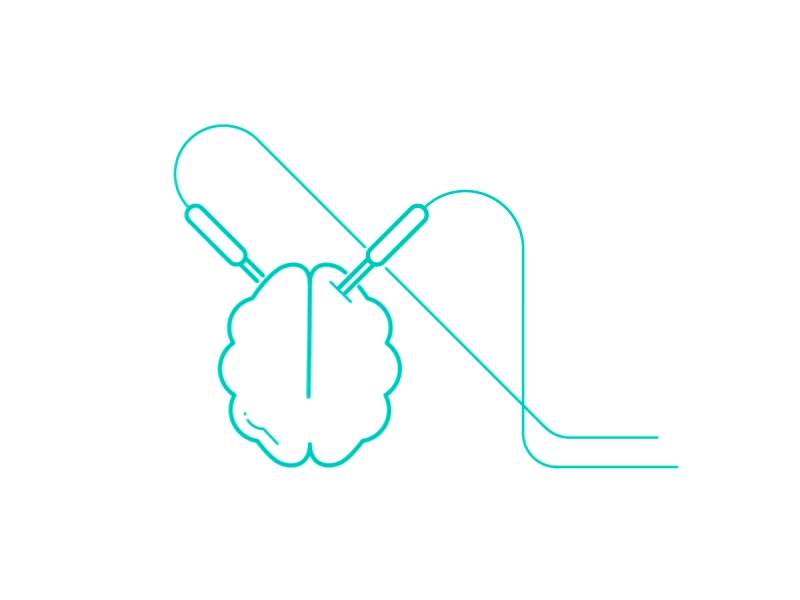

Written and Compiled by @John Nguyen of Robert Reinhart Lab on 10/15/2018, contact: Akida@bu.edu

## 0. MainMenu

Deci = [];
Deci.Folder.Raw         = ['C:\Users\User\Desktop\NE329\Module2\RawData_new'];
Deci.SubjectList = 'gui';
Deci.Step               = 4;
Deci.Folder.Version     = ['C:\Users\User\Desktop\NE329\Module2\ProcessedData'];
Deci.Retroactive  = true;

## 1. Trial Definitions

Deci.DT.Type = 'Simon_Polymerase';
Deci.DT.Starts     = {17};                                                                      % Cell Array of Markers for Start codes.
Deci.DT.Ends       = {18};                                                                      % Cell Array of Markers for End codes.
Deci.DT.Markers    = {[300 400] [31 34]};                                   % Cell Array of Markers for Trial Defs
Deci.DT.Locks      = [12 30 22];                                                                % Num Array for each timelock (usually Stim, Rsp and Fdb Onset )
Deci.DT.Toi        = [-.5 1.5];   

## 2. PreProcessing Steps

Deci.PP = [];
%Deci.PP.filter.bpfreq = [1 30];
%Deci.PP.filter.bpfilter = 'yes';

Deci.PP.ShowData = false;
Deci.ICA.do = true;

## 3. Artifact Rejection

Deci.Art.do = true;
Deci.Art.crittoilim = [-.5 1.5];
Deci.Art.Manual_Trial_Rejection = true;
Deci.Art.ShowArt = true;

## 4. Analysis

Deci.Analysis.Laplace       =false;                                                               % Uses Captrak .bvct file with same name in RawData Folder
Deci.Analysis.DownSample    = 500;

Deci.Analysis.Locks         = [1 2];                                                          % Which Lock to Analyze
Deci.Analysis.LocksTitle    = {'Stim Onset' 'Rsp Onset'};                      % Folder Title to save each Lock as
Deci.Analysis.Conditions    = {[31] [34] [300] [400]};

Deci.Analysis.CondTitle     = {'Incorrect' 'Correct' 'Congruent' 'Incongruent'};
Deci.Analysis.ERP.do  = true;

Deci.Analysis.Toilim = [-.5 1];
Deci.Analysis.Toi = [-.5 1];

## 5. Plotting

Deci.Analysis.Version = [Deci.Folder.Version];
Deci.Plot.Figures      = [true true ];

Deci.Plot.BslRef = 'Rsp Onset';

Deci.Plot.Lock = Deci.Plot.BslRef;

if  strcmpi(Deci.Plot.BslRef,'Rsp Onset')
    
    Deci.Plot.Bsl     = [-.5 -.2];
    
    Deci.Plot.Math         = {'x1 -x2'};           % Condition Math done after Bsl, Condition Indexes are appended on.
    Deci.Plot.Draw         = {[1 2] [5] [6]};                   % Cell array of Condition Index for each figure
    
    Deci.Plot.Title        = {'Incorrect vs Correct' 'Incorrect - Correct' };          % Title for each figure
    Deci.Plot.Subtitle     = {{'Incorrect' 'Correct'} {'Incorrect - Correct'}};     % Cell array of strings of subtitles for each Condition
    
    
else
    Deci.Plot.Bsl     = [-.2 0];

    
    Deci.Plot.Math         = {'x4 -x3'};           % Condition Math done after Bsl, Condition Indexes are appended on.
    Deci.Plot.Draw         = {[3 4] [5]};                   % Cell array of Condition Index for each figure
    
    Deci.Plot.Title        = {'Incogurent v Congruent' 'Incong - cong'};          % Title for each figure
    Deci.Plot.Subtitle     = {{'Incogurent v Congruent'} {'Incong - cong'}};     % Cell array of strings of subtitles for each Condition
    
end

Deci.Run.ERP =true;
Deci.Plot.GrandAverage = true;

Deci.Plot.Topo.do    =true;
Deci.Plot.Topo.Toi     = [0 .2];                   % Time of Interest
Deci.Plot.Topo.Channel = ['Reinhart-All'];                   % Channel of Interest

Deci.Plot.Wire.do    =false;
Deci.Plot.Wire.Channel =   {'FCz'};            % Channel of Interest
Deci.Plot.Wire.Toi     = [-.5 1];                   % Time of Interest

Deci.Plot.Bar.do    =false;
Deci.Plot.Bar.Toi     = [0 .2];                    % Time of Interest
Deci.Plot.Bar.Channel =  {'FCz'};            % Channel of Interest

Deci.Plot.Stat.do = false; % Will only work if for large subject pools
if Deci.Plot.Stat.do
    Deci.Plot.Stat.Type = 'Anova/T-test';
    Deci.Plot.Stat.alpha = .05;
    Deci.Plot.Stat.correctm = 'no';
end


Deci_Backend(Deci);

Deci is running retroactive subjects


Running Deci for 2 subjects
 
----------------------
Starting Analyzor for Subject #1: Simon_EEGTest1_008CG
 
Downsampling Applied
 
---Starting Condition #1: Incorrect---
 
Applying Artifact Rejection
Final trial count is 48
 
---Starting Lock #1: Stim Onset---
 
 
---Starting Lock #2: Rsp Onset---
 
 
---Starting Condition #2: Correct---
 
Applying Artifact Rejection
Final trial count is 379
 
---Starting Lock #1: Stim Onset---
 
 
---Starting Lock #2: Rsp Onset---
 
 
---Starting Condition #3: Congruent---
 
ignoring 7 trials with missing locks
Applying Artifact Rejection
Final trial count is 217
 
---Starting Lock #1: Stim Onset---
 
 
---Starting Lock #2: Rsp Onset---
 
 
---Starting Condition #4: Incongruent---
 
ignoring 12 trials with missing locks
Applying Artifact Rejection
Final trial count is 210
 
---Starting Lock #1: Stim Onset---
 
 
---Starting Lock #2: Rsp Onset---
 
Analyzed for Simon_EEGTest1_008CG Time: 97.416
----------------------
Starting Analyzor for Subject #2:

Error using Deci_Backend (line 185)
LocksTitle ~= to Locks length